# **天线阵的方向图演示（利用实时脚本等解析计算）**

**        若干个辐射单元按一定规律排列起来所构成的天线系统，称为天线阵。组成天线阵的辐射单元称为阵元，阵元可以是任何类型的单一天线。按单元天线的排列方式可将天线阵分为直线阵、平面阵和立体阵。立体阵可从平面阵推广得到，平面阵可从直线阵推广得到，而直线阵可由二元阵推广得到。在端射式天线阵中，各单元天线上电流的相位应依次滞后一个角度**$\xi$**，这个角度**$\xi$**在数值上等于相邻两单元天线之间的距离在**$$$\varphi=0^{\circ}$$$**方向上所引起的相位差**$$$k_{0}d$$$**。当**$$$\xi=k_{0}d$$$**时，两相邻单元天线所产生的场在**$$$\varphi=0^{\circ}$$$**方向上的波程所引起的相位差**$$$k_{0}d$$$** 正好与它们自身电流的相位差**$$$\xi=k_{0}d$$$**相补偿，从而使得在**$$$\varphi=0^{\circ}$$$**方向上所有单元天线产生的场同相叠加而达到最大值。**

**        端射式等幅直线阵的阵因子为**


$$f_a (\varphi )=\frac{\sin \lbrack \frac{Nk_0 d}{2}(\cos \varphi -1)\rbrack }{\sin \lbrack \frac{k_0 d}{2}(\cos \varphi -1)\rbrack }$$


**        其归一化形式为**


$$f_a (\varphi )=\frac{\sin \lbrack \frac{Nk_0 d}{2}(\cos \varphi -1)\rbrack }{\textrm{Nsin}\lbrack \frac{k_0 d}{2}(\cos \varphi -1)\rbrack }$$


**        本小节以4元端射式天线阵为例演示。**

- **定义参数**

phi=linspace(0,2*pi);                %方位角
theta=linspace(0,pi);                %头顶仰角
lambda=1;                            %波长
k0=2*pi/lambda;                      %波数
d=lambda/2;                          %单元间距
N=4;          %单元天线个数

- **计算二维方向图（xoy平面）**

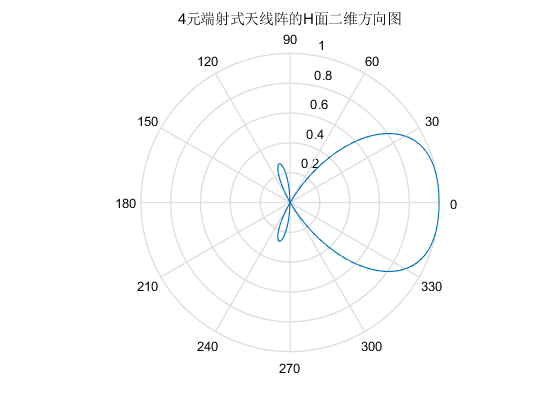

f=sin(N*k0*d/2*(cos(phi)-1))./(sin(k0*d/2*(cos(phi)-1))*N);      
                                     %归一化方向图函数，xoy平面
figure(1);
polar(phi,f);                        %绘制二维方向图函数
title([num2str(N),'元端射式天线阵的H面二维方向图'])
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **旋转得到三维方向图**

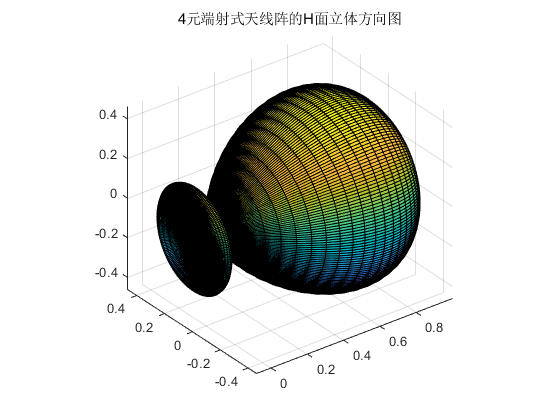

y1=(f.*sin(phi))'*cos(theta);        %绕x轴旋转得到曲面，计算y值
z1=(f.*sin(phi))'*sin(theta);        %绕x轴旋转得到曲面，计算z值
x1=(f.*cos(phi))'*ones(size(theta)); %绕x轴旋转得到曲面，计算x值
figure(2)
surf(x1,y1,z1);                      %绘制曲面
title([num2str(N),'元端射式天线阵的H面立体方向图']);
axis equal;                          %设置各个轴等比例显示
set(gcf,'Visible','on');   	    %强制图片弹出显示